states_0 = state_vec_to_struct(zeros(30, 1))

states_0 = struct with fields:
     posn_body: [3×1 double]
      vel_body: [3×1 double]
     quat_body: [1×1 quaternion]
        bias_f: [3×1 double]
    bias_omega: [3×1 double]
       posn_bv: [3×1 double]
       quat_vb: [1×1 quaternion]
      posn_tag: [3×1 double]
      quat_tag: [1×1 quaternion]


states_0.posn_body = [1, 0, 0]';
states_0.vel_body = [0, 1, 0]';
states_0.quat_body = quaternion([0, 0, 0], 'eulerd', 'xyz', 'frame');

states_0.quat_vb = quaternion([1, 0, 0, 0]);

states_0.posn_tag = [1, 0, 0]';
states_0.quat_tag = quaternion([1, 0, 0, 0]);

v_states_0 = state_struct_to_vec(states_0);

f = [0, 0, 0];
omega = [0.2, 0, pi/6];

u = [f(:); omega(:)];

t_0 = 0;
t_end = 10;
dt = 1/15;

iterations = (t_end - t_0) / dt;
mat_u = repelem(u, 1, iterations);

%{
mat_u(3, 1:2) = 1;
mat_u(3, 4:7) = -1;
mat_u(4:6, 8:end) = repelem([0; 0; 0], 1, iterations - 8 + 1);
mat_u(1:3, 8:11) = repelem([1/sqrt(2); 1/sqrt(2); 0], 1, 4);
%}

mat_u(6, 1:end) = pi/6;
mat_u(3, 1:end/2) = 1;
mat_u(3, end/2:end) = -2;
disp(mat_u);

  Columns 1 through 9

         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
         0         0         0         0         0         0         0         0         0
    0.5236    0.5236    0.5236    0.5236    0.5236    0.5236    0.5236    0.5236    0.5236

  Columns 10 through 18

         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
         0         0         0         0 

use_ode45 = true;

tic
[t_out, structs_states, states_out] = sim_state_transition(v_states_0, mat_u, dt, use_ode45);
elapsed_time = toc;
fprintf("Max prediction speed: %.2fHz", size(mat_u, 2)/elapsed_time)

Max prediction speed: 7.83Hz

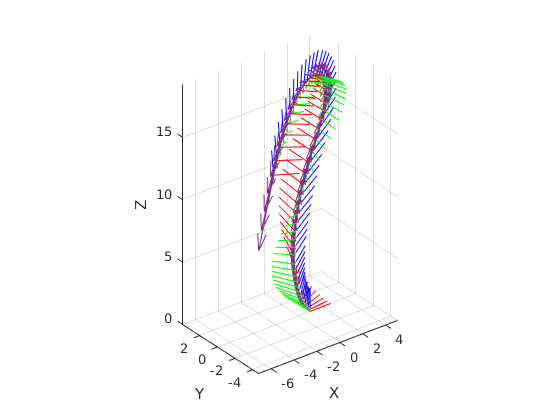


tab_states = states_structs_to_tab(structs_states);

plot_points = 50;

% Ceiling
if plot_points > length(structs_states)
    plot_points = length(structs_states);
end

% Generate the indices
% We don't want to plot the final point
plot_indices = round(linspace(1, length(structs_states) - 1, plot_points));

viz_state_transition(structs_states(plot_indices), mat_u(:, plot_indices));

tab_states.posn_tag

ans =     1.0000         0         0
    0.9971   -0.1015   -0.0011
    0.9883   -0.2029   -0.0044
    0.9736   -0.3038   -0.0099
    0.9531   -0.4041   -0.0176
    0.9268   -0.5035   -0.0276
    0.8947   -0.6019   -0.0398
    0.8570   -0.6991   -0.0543
    0.8135   -0.7948   -0.0710
    0.7645   -0.8889   -0.0900


posn_bv_rotated_world_orntn = rotatepoint(tab_states.quat_body, tab_states.posn_bv);
posn_tag_rotated_world_orntn = rotatepoint(tab_states.quat_body, rotatepoint(conj(tab_states.quat_vb), tab_states.posn_tag));

posn_tag_world = tab_states.posn_body + posn_bv_rotated_world_orntn + posn_tag_rotated_world_orntn

posn_tag_world =     2.0000         0         0
    2.0012    0.0000   -0.0004
    2.0023    0.0000   -0.0009
    2.0035    0.0001   -0.0013
    2.0046    0.0002   -0.0018
    2.0058    0.0003   -0.0022
    2.0069    0.0005   -0.0027
    2.0081    0.0006   -0.0031
    2.0092    0.0009   -0.0035
    2.0104    0.0011   -0.0040
